# 题目5：HSI转RGB

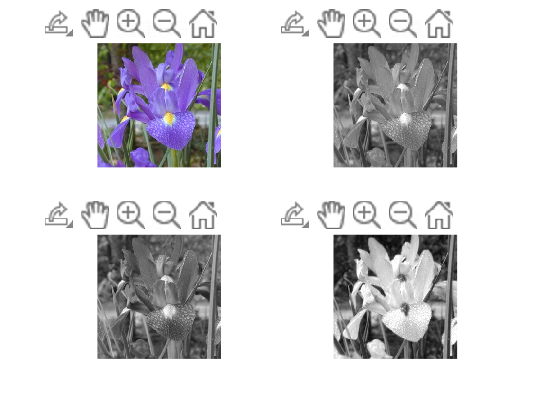

H = H * 2 * pi; % 恢复为[0, 2π]

% 转换
img_hsi = cat(3, H, S, I);
R = zeros(size(H)); G = zeros(size(H)); B = zeros(size(H));

% 分情况计算RGB
region = floor(H / (2*pi/3)); % 将H分为0°, 120°, 240°三个区域
region = mod(region, 3); % 确保区域在0-2之间

for i = 1:size(H,1)
    for j = 1:size(H,2)
        h = H(i,j);
        s = S(i,j);
        i_val = I(i,j);
        if region(i,j) == 0 % 0°-120°
            B(i,j) = i_val * (1 - s);
            R(i,j) = i_val * (1 + s*cos(h)/cos(pi/3 - h));
            G(i,j) = 3*i_val - (R(i,j) + B(i,j));
        elseif region(i,j) == 1 % 120°-240°
            h = h - 2*pi/3;
            R(i,j) = i_val * (1 - s);
            G(i,j) = i_val * (1 + s*cos(h)/cos(pi/3 - h));
            B(i,j) = 3*i_val - (R(i,j) + G(i,j));
        else % 240°-360°
            h = h - 4*pi/3;
            G(i,j) = i_val * (1 - s);
            B(i,j) = i_val * (1 + s*cos(h)/cos(pi/3 - h));
            R(i,j) = 3*i_val - (G(i,j) + B(i,j));
        end
    end
end

% 合并RGB并限制范围[0,1]
img_recon = cat(3, R, G, B);
img_recon = max(min(img_recon, 1), 0);

% 显示RGB分量
figure;
subplot(2,2,1), imshow(img_recon), title('重建RGB');
subplot(2,2,2), imshow(R), title('R分量');
subplot(2,2,3), imshow(G), title('G分量');
subplot(2,2,4), imshow(B), title('B分量');